Lab 1, Harrison Robel, Partner: Karen Gong

clear; close all;

## Problem 1: A little Statistics

The normal distribution is a distribution that occurs naturally in many different probability distributions, such as height. The normal distribution is usually symmetric, this is the Gaussian distribution. The downside of the Gaussian distribution, more specifically of a linear Y-axis, is that many distributions will look like Gaussian until you zoom in on the tails where it can be fairly far off from the normal curve.

To find the "sigma" value of any distribution you start by finding the probability that a signal would not come from the background noise by integrating from the given x value in question to infinity of the distribution using the .cdf function. Once a probability is obtained then the inverse of the .cdf function (normcdf) can be used to reference the normal distribution giving a "sigma" value by integrating from right to left until the probability from the first function is found.

X1 = normcdf(1)

X1 = 0.8413

X2 = normcdf(2)

X2 = 0.9772

X3 = normcdf(5)

X3 = 1.0000


Y1 = norminv(X1)

Y1 = 1

Y2 = norminv(X2)

Y2 = 2.0000

Y3 = norminv(X3)

Y3 = 5.0000

Inputting any given sigma into the 'normcdf' function gives the probability that you will find a value past the sigma value. To return back to the sigma value (or obtain a new sigma value) then the "norminv" function is used to integrate from right to left until the probability inputted is found, which is associated with a sigma value.

Y4 = norminv(0.1)

Y4 = -1.2816

X4 = normcdf(-1.2816)

X4 = 0.1000

When imputting a small probabilty into the "norminv" the sigma value outputted becomes negative. Negative sigma values represent that the value is to the left of the mean. This occurs when the probability is less than 0.5.

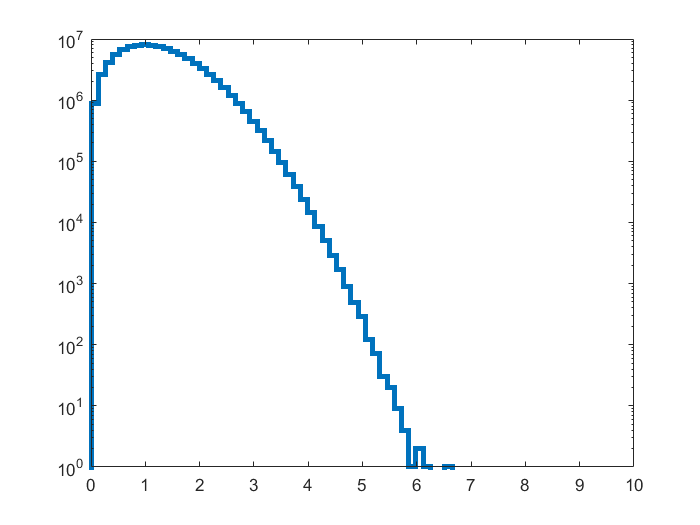

d = raylrnd(1,10000);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([0,10])
set(gca, 'YScale', 'log')

My hypothetical data points that I tested were 3,2, and 0.5. The question with these data points is; What is the probability, in terms of sigma, that the data in question is not produced by random chance? To represent the question mathematically you can take the integral from x to infinity (where x is the data point checking) of the cdf function in this case it will be raylcdf(x). Then find sigma by taking the integral from infinity to x of the normcdf function to find sigma.

Z1 = raylcdf(4,1)

Z1 = 0.9997

Z2 = raylcdf(3,1)

Z2 = 0.9889

Z3 = raylcdf(0.5,1)

Z3 = 0.1175

SIGMA_1 = norminv(Z1)

SIGMA_1 = 3.4012

SIGMA_2 = norminv(Z2)

SIGMA_2 = 2.2866

SIGMA_3 = norminv(Z3)

SIGMA_3 = -1.1876

The probabilites and sigmas change as expected. As the X value gets smaller, the probability gets smaller as well. With a smaller probability comes a smaller sigma until the probability is less than a half where the probability becomes negative and continues to become more negative.

## Problem 2: Non-Continous Distributions

The Poisson distribution is a case of the binomial distribution where the probabilites of an event occuring is very low. Normally in a Poisson distribution the highest probabilites are low count values such as 0 or 1. The 'nu' parameter sets what the average value is. Something different from the binomial distribution is that the average value can be a non integer value. 

Plot 1

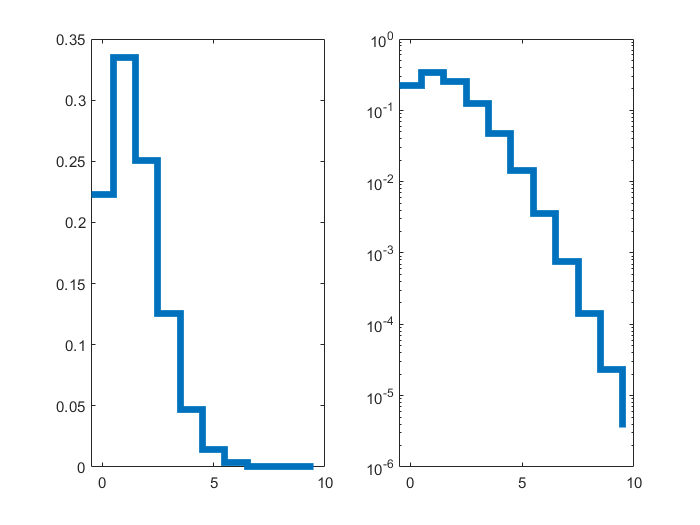

x = 0:10;
poisson = makedist("Poisson", 'lambda',1.5); 
%nu=1 makes a lorentz distribution as a special case
subplot(1,2,2)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(1,2,1)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);

Plot 2

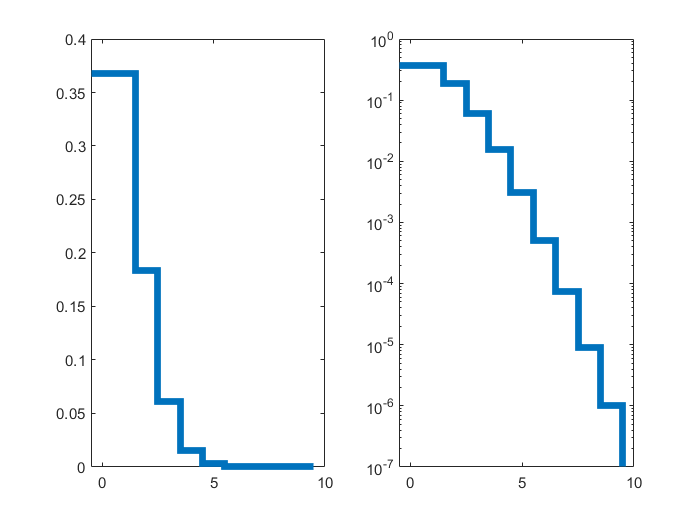

x = 0:10;
poisson = makedist("Poisson", 'lambda',1.0); 
%nu=1 makes a lorentz distribution as a special case
subplot(1,2,2)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(1,2,1)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);

Plot 3

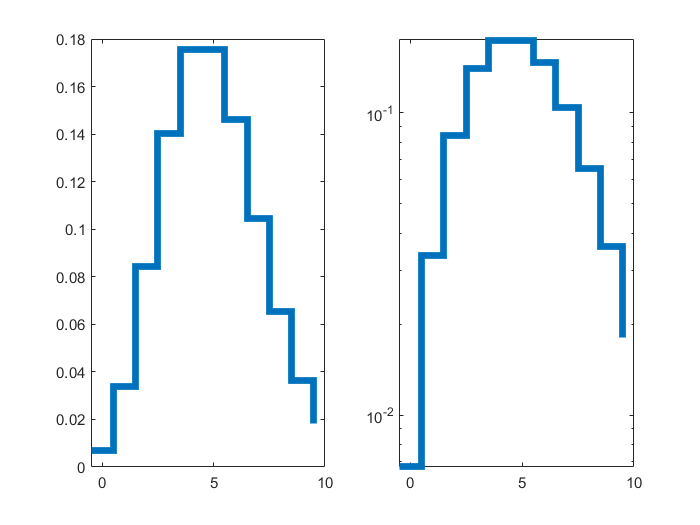

x = 0:10;
poisson = makedist("Poisson", 'lambda',5); 
%nu=1 makes a lorentz distribution as a special case
subplot(1,2,2)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(1,2,1)
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);

The question with a Poisson distribution is similar as in the rayleigh distribution above. What is the probability that a signal from a radioactive Uranium source is produced from the background radiation of Uranium? To answer this question take the integral from the signal to infinity of the cdf function for a Poisson distribution and use the invnorm function to create a sigma value. 

P1 = poisscdf(7,1.5)

P1 = 0.9998

PSIGMA_1 = norminv(P1)

PSIGMA_1 = 3.5834

Because the distribution is discrete, the cdf value returns a discrete value which in turn gives a discrete sigma value. This happens because the integral of the distribution is taking the area under a series of rectangles so the integral does not continue to infiinty but rather ends when there are no longer counts at further x values.

One of the things with a Poisson distribution that is not discrete is the mean value. This is the case because the mean is not always the value that occurs the most, rather there are an equal amount of counts above that average as there are below. This means that the average is where the distribution is skewed but not necessarily where the highest amount of counts occurs. 